# Solução do problema de fluxo de potência.

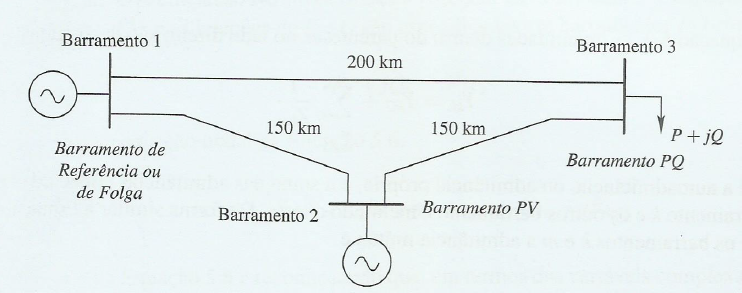

#### MOHAN, N. ."ELECTRIC POWER SYSTEM: A FIRST COURSE". Danver, MA: John Wiley & Sons Inc.. 2012. cap. 5. página 89. exemplo 5.4.



clear 
clc


## Número de barramentos (entrada do usuário):

numBarra = 3;

São criada as matrizes e variáveis que serão utilizadas ao longo do programa.

SLACK = 1;
PV = 2;
PQ = 3;
matriz_P = sym("P" , [numBarra , 1]);
matriz_Q = sym("Q" , [numBarra , 1]);
assume(matriz_Q, 'real');
matriz_theta = sym("theta" , [1 , numBarra]);
matriz_V = sym("V" , [1 , numBarra]);
matriz_YG = zeros(numBarra , 1);



## Especificações de impedância do sistema (entrada do usuário):

### Impedância da linha de transmissão:

    Se faz indispensável definir o valor das impedâncias das LTs para que o programa funcione corretamente. Seus valores são especificados em p.u. (por unidade). Para defini-la, deve-se atribuir o valor matriz_Z( p, q ), onde **p** é o barramento extremo de entrada da LT, e **q** é o barramento do extremo de saida. Caso não haja LT entre os barramentos p,q, deve-se definir seu valor de impedância como zero ( matriz_Z( p , q ) = 0 ).

    Como estamos resolvendo o problema 5.4 especificado, iremos preencher com os dados do mesmo:

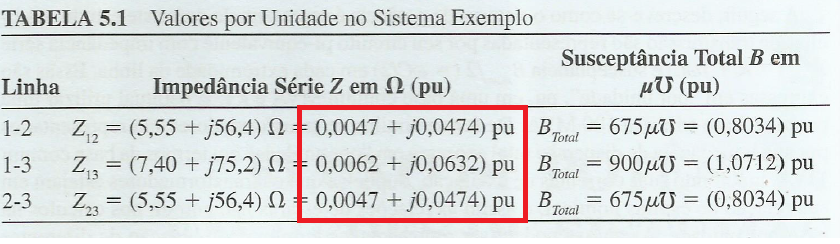

% Input do usuário: especificações das Linhas de Transmissão (LTs):
matriz_Z = zeros(numBarra,numBarra);

% Impedância da LT entre os barramentos 1-2 ou 2-1 (em p.u.):
matriz_Z(1,2) = 0.0047 + j*0.0474;
matriz_Z(2,1) = 0.0047 + j*0.0474;

% Impedância da LT entre os barramentos 1-3 ou 3-1(em p.u.):
matriz_Z(1,3) = 0.0062 + j*0.0632;
matriz_Z(3,1) = 0.0062 + j*0.0632;

% Impedância da LT entre os barramentos 2-3 ou 3-2(em p.u.):
matriz_Z(2,3) = 0.0047 + j*0.0474;
matriz_Z(3,2) = 0.0047 + j*0.0474;




### Impedância entre o barramento e a terra:

    É possível que não seja especificado ou utilizado este valor no problema. Caso seja o caso, apenas deixe de preenche-lo. Abaixo apenas são atribuidos como zero para enfatizar a sua existência no problema.

    Como no caso em análise esta **não é especificada**, deixaremos como zero os valores respectivos..


% Admitância barramento-terra na barra 1, em p.u.:
matriz_YG(1) = 0 ;

% Admitância barramento-terra na barra 2, em p.u.:
matriz_YG(2) = 0 ;

% Admitância barramento-terra na barra 3, em p.u.:
matriz_YG(3) = 0 ;



### Matriz admitância:

    Após especificados todos parâmetros relacionando impedâncias no sistema, chama-se a função **matriz_admitancia() **, a qual faz o cálculo da matriz admitância do sistema em questão.

% Formando a matriz admitância:
matriz_Y = matriz_admitancia(matriz_Z, matriz_YG);


### Análise da matriz admitância (Y):

    Analisando a saida da função **matriz_admitância() **já é possível que seus dados estão de acordo com os constados no livro:

Dados do programa:

Dados do livro:

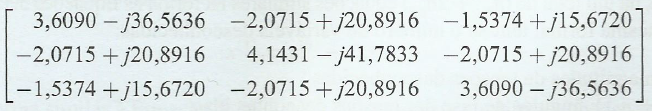

## Especificações dos dados dos barramentos **(entrada do usuário)**:

    Nesta seção deverão ser especificados os dados dos n barramentos ( no caso numBarra = 3 barramentos). Cada barramento pode ser um dos três tipos: barramento de **Referência** ou **Folga **(ou Slack em inglês), **PV** ou **PQ.** Cada tipo de barramento deve ser especificados valores diferentes:

- **SLACK: **Deverá ser especificado um valor para tensão (** matriz_V( p ) **) , onde p é o número do barramento em questão) e o valor do ângulo de fase deve ser zero ( **matriz_theta( p )** = 0 ).

- **PV: **Deverá ser especificado um valor para potência ativa P ( **matriz_P( p )** ) e para tensão (** matriz_V( p ) **).

- **PQ**: Deverá ser especificado um valor para potência ativa P ( **matriz_P( p )** ) e para potência reativa Q ( **matriz_Q( p )** ).

 Para tal, deve-se associar cada barramento ao seu tipo, i.e. Tipo_barra(p) = {"SLACK" , "PV" ou "PQ"}. O valor especificado deverá constar exatamente igual ao conteúdo entre aspas, sendo o correto **Tipo_barra(p) = "SLACK"**, e por exemplo, o incorreto Tipo_barra(p) = slack ou Tipo_barra(p) = Slack.


% Input do usuário: especificações dos barramentos:
% Se for barra tipo SLACK, deve-se definir o valor da tensão (1 p.u.) e ângulo (0 rad)
% Se for barra tipo PV, deve-se definir Potência ativa em p.u. e magnitude da tensão em p.u..
% Se for barra tipo PQ, deve-se definir Potência ativa em p.u. e Potência reativa em p.u..


% Barramento 1: SLACK
Tipo_barra(1) = SLACK;
matriz_V(1) = 1.0;
matriz_theta(1) = 0;



% Barramento 2: PQ
Tipo_barra(2) = PV;
matriz_P(2) = 2.00;
matriz_V(2) = 1.05;

% Barramento 3: PQ
Tipo_barra(3) = PQ;
matriz_P(3) = -5.00;
matriz_Q(3) = -1.00;


### Potência especificada:

    Forma um vetor coluna contendo os valores previamente especificados de potência ativa e reativa, assim como os valores não especificados, em forma de variáveis livres:

P_esp = vpa(matriz_P + j * matriz_Q);


No exemplo em questão, P_esp teria contido em suas linhas:

P_esp = 

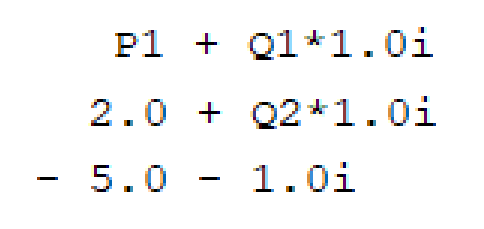

## Obtendo vetor coluna conténdo variáveis e chutes para o método Newthon-Raphson:

    Conforme necessário no método Newthon-Raphson, um vetor com valores iniciais para as variáveis livres das funções se faz necessário. Além disso, é necessário conhecer quais são as variáveis livres em si para o cálculo das derivadas parciais (Jacobiano). Então é chamada a função **obter_dadosNR() **que realiza todas as tarefas descritas acima.


% Construindo o vetor chute X0 e as variáveis para o método NR:
[X0 , variaveis_NR] = obter_dadosNR(Tipo_barra);

A saida da função **obter_dadosNR() **é um vetor coluna chute X0 e um vetor linha contendo todas variáveis livres do sistema.

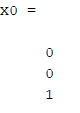

    Vale salientar que os elementos de **X0** ,apesar de ser um vetor coluna, são respectivamente equivalentes ao chute inicial das variáveis contidas no vetor linha **variaveis_NR** , onde os valores inicias são: theta2 = 0 , theta3 = 0 e V3 = 0.


% Contando número de barramentos PV e PQ:
[nPV , nPQ] = contBarramentos(Tipo_barra);


## Equações básicas de fluxo de potência:

    Conforme deduzido no livro, utilizando as fórmulas:

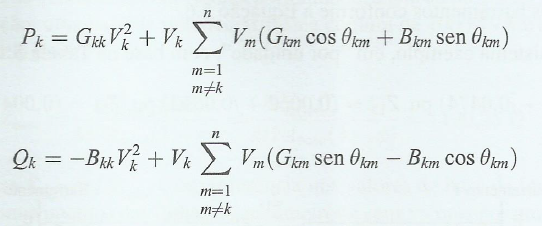

Obtém-se da função **func_potencia() **dois vetores colunas: **equacao_potencia_NR **que contém as funções em forma de texto das potências deconhecidas (descrita acima) e **f_potencia_geral **que contém as potências conhecidas ( especificadas anteriormente ) e as desconhecidas ( descritas acima).

% Obtendo as equações de potência:
[equacao_potencia_NR , f_potencia_geral] = func_potencia(nPV , nPQ , P_esp, Tipo_barra ,matriz_V , matriz_theta, matriz_Y);


### Função de potência geral:

    Constroi-se a função numérica **P_numeric_geral** propriamente dita a partir do vetor **f_potencia_geral** contendo as funções em forma de texto.


sym_P_geral = symfun(f_potencia_geral , variaveis_NR);
P_numeric_geral = matlabFunction(sym_P_geral);


## Método Newton-Raphson:

    Em posse das previamente calculadas equações básicas de potência em forma de texto ( **equacao_potencia_NR **) , variáveis livres do sistema ( **variaveis_NR **) e chute das variáveis livres ( **X0** ) poderá ser calculada as raízes das equações de potência. Além disso, deverá ser especificado uma tolerância para as raízes obtidas e um número limite de iterações.

maximo_de_iteracoes = 1000;
tolerancia = 1.0e-20;
[final_X , final_JAC , iteracoes] = NewtonRaphson(equacao_potencia_NR , variaveis_NR ,  , maximo_de_iteracoes, tolerancia);


### Saída do método Newton-Raphson:

    Depois de ser realizado o método Newthon-Raphson por meio da função de mesmo nome: **NewtonRaphson() **é retornado dela três parâmetros:

- **final_X**: vetor coluna contendo as raizes aproximadas das equações de potência.

- **final_JAC**: o valor numérico do jacobiano da última iteração

- **iteracoes**: número de iterações necessárias para alcançar os valores descritos acima.

### Impressão dos dados relevantes:

    Por fim, chamando funções personalizadas printP_barras() , printX()  são impresso os dados na tela de comandos do usário

fprintf("Número de iterações = %d ", iteracoes);

Número de iterações = 10000 


cell_X = num2cell(final_X);
P_das_barras = P_numeric_geral(cell_X{:});
printP_barras(P_das_barras);



Potência fornecida por cada barramento. 
 n |     P + Q*i [p.u.]
------------------------------
 1 |    3.08405-0.814722i 
 2 |    2.00000+2.666249i 
 3 |   -5.00000-1.000000i 



printX(variaveis_NR , final_X, matriz_V, matriz_theta);



Tensão e ângulo nos barramentos.
 n |     V  [p.u.]|  θ [rad]
------------------------------
 1 |    1.00000   |    0.00000 
 2 |    1.05000   |   -0.03612 
 3 |    0.97806   |   -0.15343 



[P_nas_LTs] = flxuo_potencia_LT(variaveis_NR , final_X , matriz_V, matriz_theta, matriz_Z);
printP_LTs(P_nas_LTs);



Fluxo de potência ativa e reativa entre os barramentos p e q.
  p -> q |    P + Q * i [p.u.]   
---------------------------------
  1 -  2 |    0.65112-1.119415i 
  1 -  3 |    2.43826+0.107966i 
  2 -  1 |   -0.64324+1.198907i 
  2 -  3 |    2.77520+1.229044i 
  3 -  1 |   -2.40132+0.268501i 
  3 -  2 |   -2.73598-0.833446i 
